# Solutions for ME6130 - Lab Tutorial

### The Carbon Fiber (CF) TCAM modelling and Simulation work

clear all; close all;
MaterialType = 'CF';     % or 'Nylon'
loadTCAMParameters(MaterialType);

✔ Parameters loaded for CF


#### Plot the CF experimental results

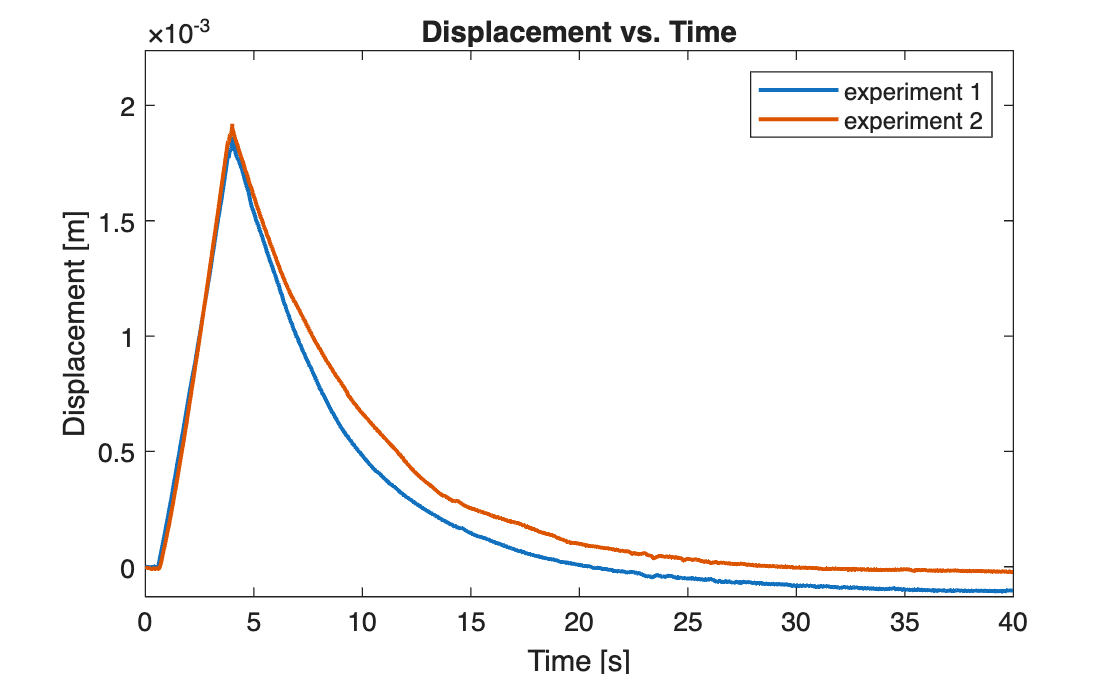

fig1 = figure(1);
plot(Time,Disp,'-',LineWidth=1.5)
legend('experiment 1','experiment 2')
xlabel('Time [s]')
ylabel('Displacement [m]')
ylim([min(Disp(:,1))*1.2 max(Disp(:,1))*1.2])
title('Displacement vs. Time')

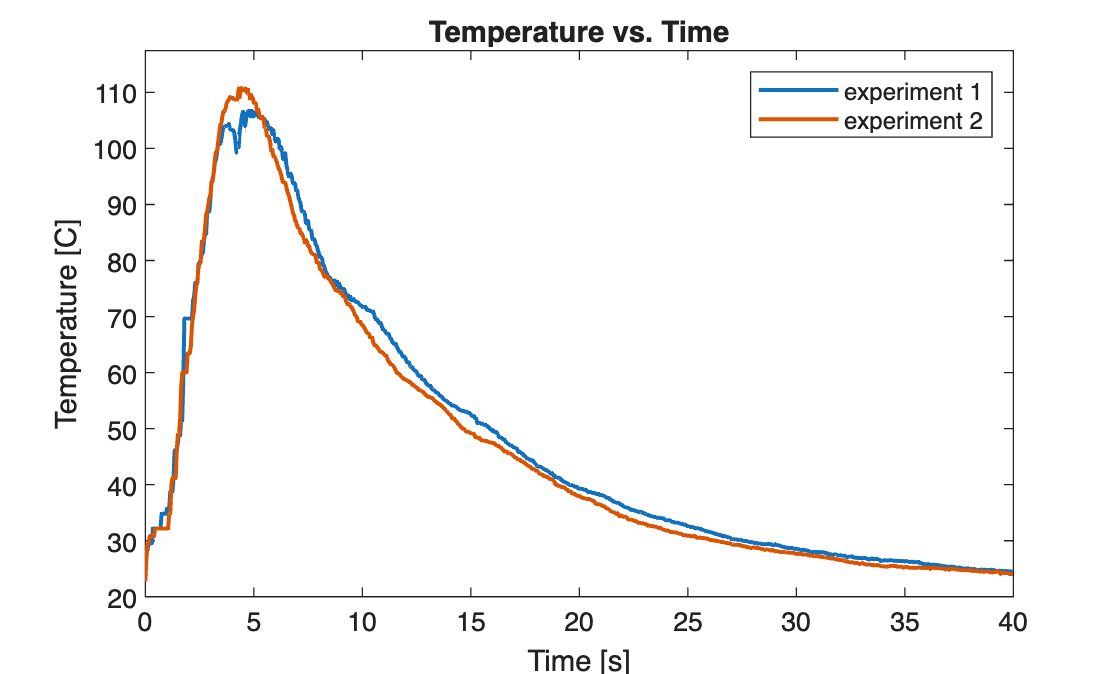

fig2 = figure(2);
plot(Time,Temp,'-',LineWidth=1.5)
legend('experiment 1','experiment 2')
xlabel('Time [s]')
ylabel('Temperature [C]')
ylim([20 max(Temp(:,1))*1.1])
title('Temperature vs. Time')

#### Generate the Simulated plots for CF

out = sim('Sim_model_LS.slx')

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [801x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Plot both simulated and experimental results on the same plot for CF

plotTCAMResults();

### The Nylon TCAM modelling and Simulation work

clear all; close all;
MaterialType = 'Nylon';     % or 'Nylon'
loadTCAMParameters(MaterialType);

✔ Parameters loaded for Nylon


#### Plot the Nylon experimental results

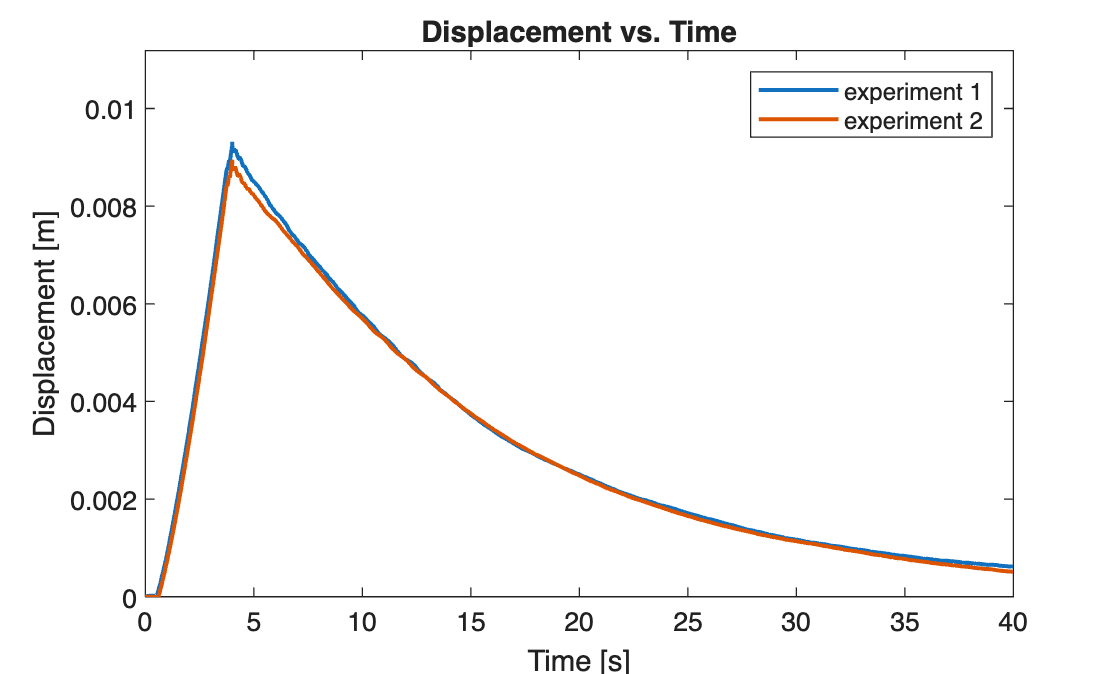

fig1 = figure(1);
plot(Time,Disp,'-',LineWidth=1.5)
legend('experiment 1','experiment 2')
xlabel('Time [s]')
ylabel('Displacement [m]')
ylim([min(Disp(:,1))*1.2 max(Disp(:,1))*1.2])
title('Displacement vs. Time')

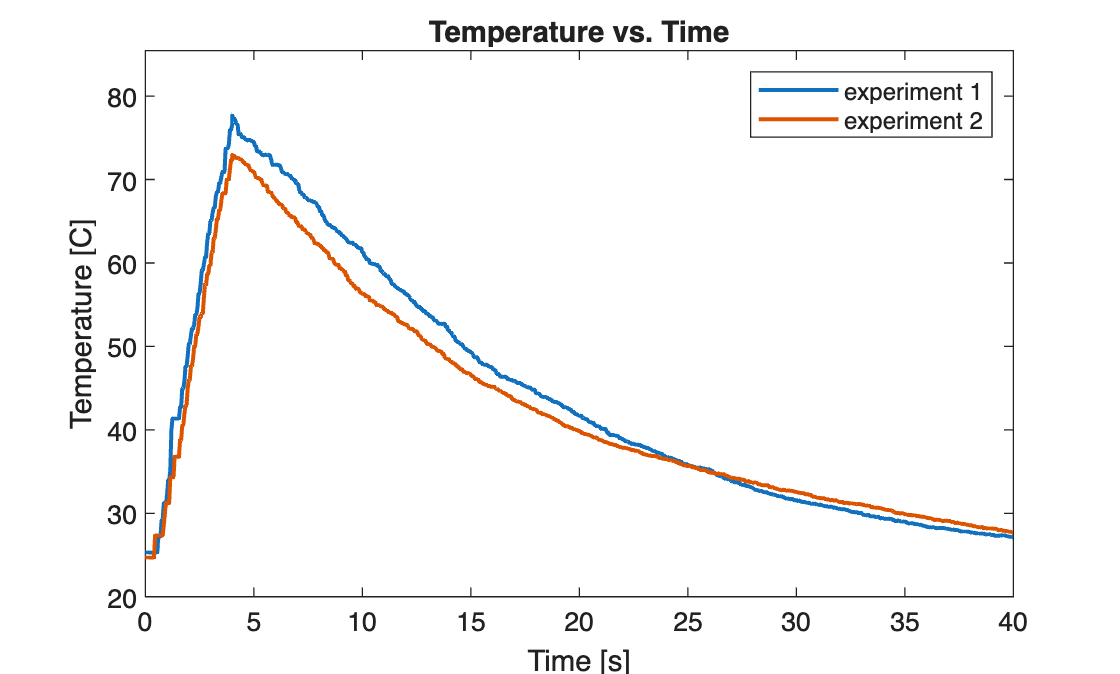

fig2 = figure(2);
plot(Time,Temp,'-',LineWidth=1.5)
legend('experiment 1','experiment 2')
xlabel('Time [s]')
ylabel('Temperature [C]')
ylim([20 max(Temp(:,1))*1.1])
title('Temperature vs. Time')

#### Generate the Simulated plots for Nylon

out = sim('Sim_model_LS.slx')

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [801x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


#### Plot both simulated and experimental results on the same plot for Nylon

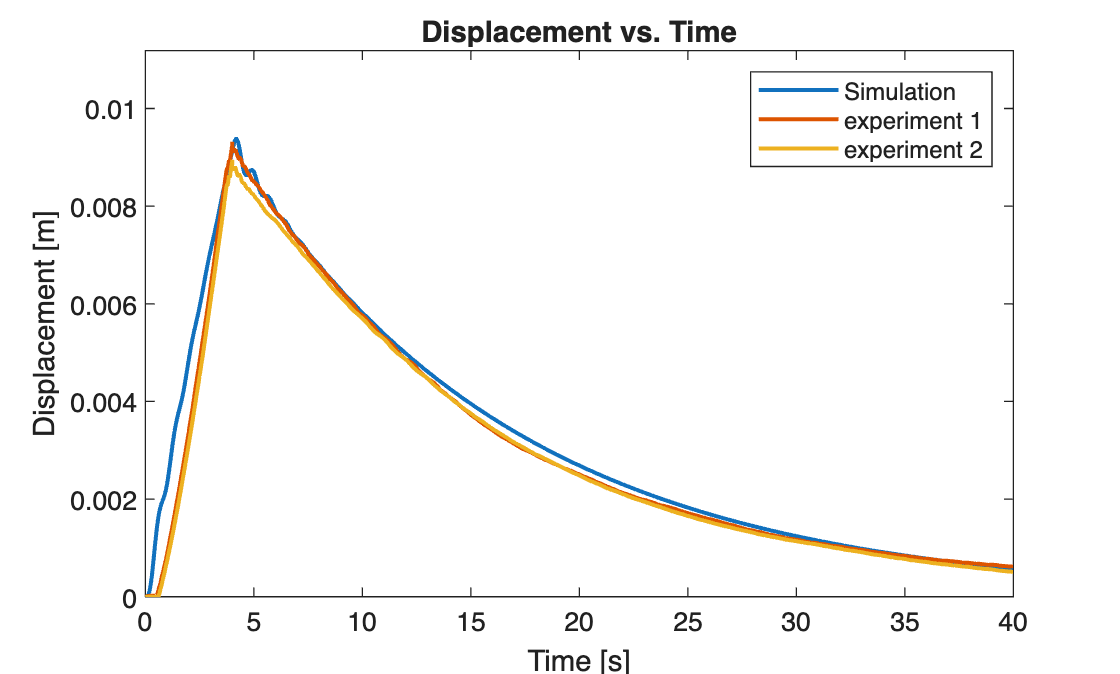

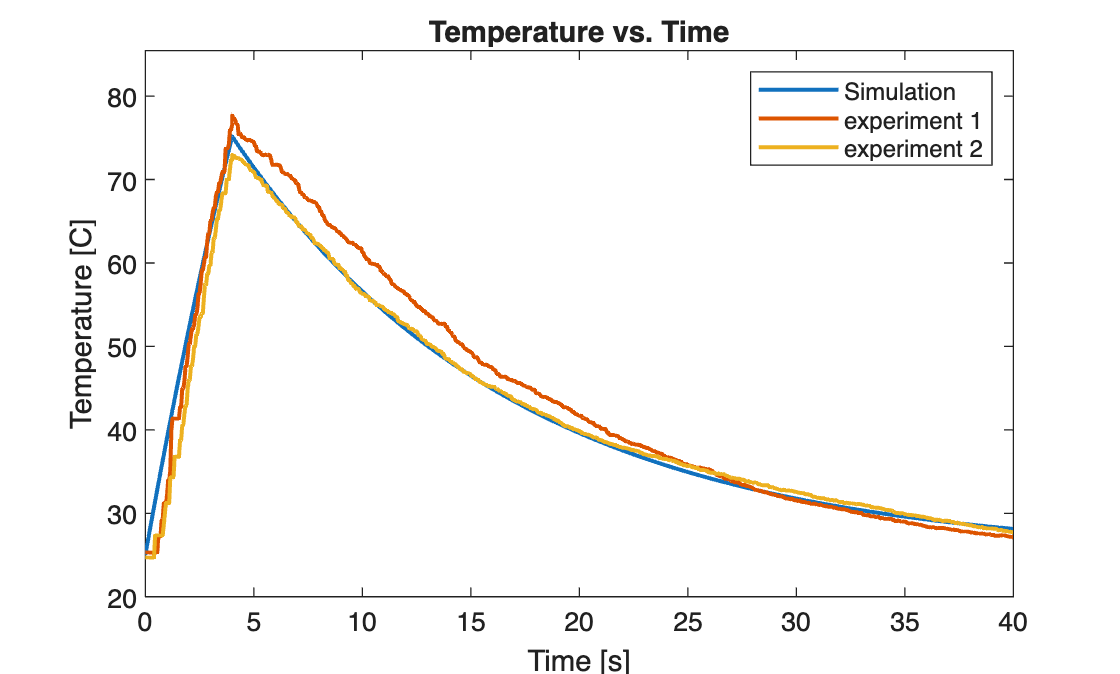

plotTCAMResults();